dt=1/1000;
t=0:dt:1;
f=15;
sig=sin(2*pi*f*t);
h=transpose(hann(length(sig)));
flat=transpose(flattopwin(length(sig)));

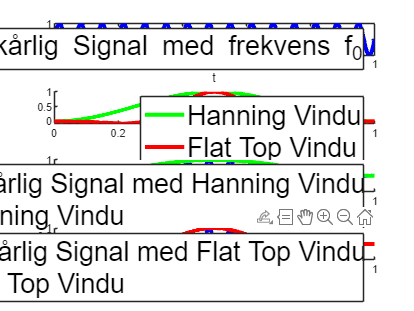

figure;

subplot(4,1,1);
plot(t,sig,'Color','b','LineWidth',3);
xlabel("t");
legend("Vilkårlig Signal med frekvens f_0",'FontSize',20)

subplot(4,1,2);
hold on;
plot(t,h,'Color','g','LineWidth',3);
plot(t,flat,'Color','r','LineWidth',3);
xlabel("t");
legend("Hanning Vindu","Flat Top Vindu",'FontSize',20)


subplot(4,1,3);
hold on;
plot(t,sig.*h,'Color','b','LineWidth',3)
plot(t,h,'Color','g','LineWidth',3);
xlabel("t");
legend("Vilkårlig Signal med Hanning Vindu", "Hanning Vindu",'FontSize',20)


subplot(4,1,4);
hold on;
plot(t,sig.*flat,'Color','b','LineWidth',3);
plot(t,flat,'Color','r','LineWidth',3);
xlabel("t");
legend("Vilkårlig Signal med Flat Top Vindu", "Flat Top Vindu",'FontSize',20)

N_fft=2.^14;
f_fft=(1/(dt*N_fft))*(-N_fft/2:N_fft/2-1)

f_fft =  -500.0000 -499.9390 -499.8779 -499.8169 -499.7559 -499.6948 -499.6338 -499.5728 -499.5117 -499.4507 -499.3896 -499.3286 -499.2676 -499.2065 -499.1455 -499.0845 -499.0234 -498.9624 -498.9014 -498.8403 -498.7793 -498.7183 -498.6572 -498.5962 -498.5352 -498.4741 -498.4131 -498.3521 -498.2910 -498.2300 -498.1689 -498.1079 -498.0469 -497.9858 -497.9248 -497.8638 -497.8027 -497.7417 -497.6807 -497.6196 -497.5586 -497.4976 -497.4365 -497.3755 -497.3145 -497.2534 -497.1924 -497.1313 -497.0703 -497.0093



A=fftshift(fft(sig,N_fft));
B=fftshift(fft(sig.*h,N_fft));
C=fftshift(fft(sig.*flat,N_fft));

S_A=20*log10(abs(A)./max(abs(A)));
S_B=20*log10(abs(B)./max(abs(B)));
S_C=20*log10(abs(C)./max(abs(C)));

figure;
ax = gca

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


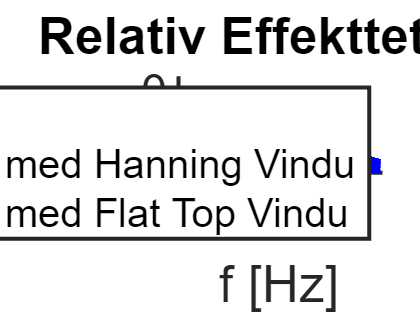

ax.LineWidth = 3;
ax.FontSize=35;
hold on;
plot(f_fft,S_A,'Color','b','LineWidth',2);
plot(f_fft,S_B,'Color','g','LineWidth',2);
plot(f_fft,S_C,'Color','r','LineWidth',2);
xlabel("f [Hz]");
ylabel("[dB]")
ylim([-60 10]); xlim([-60 60]);
xticks([-f f]); xticklabels(["-f_0" "f_0"]);
legend("Vilkårlig Signal", "Vilkårlig Signal med Hanning Vindu", "Vilkårlig Signal med Flat Top Vindu",'FontSize',30);
set(get(gca,'ylabel'),'rotation',0);
title("Relativ Effekttetthet");